clear
sentences = {'This is a sentence I promise, I also promise Im running.', 'Without sentences the world would be very boring.', 'Running is not the same as run but walking is the same as running slow, I think.'};

% Load the stop words (MATLAB has a built-in stop word list)
stopWords = stopWords("Language", "en");

% Initialize an empty cell array to hold the processed words
processedWords = {};

% Loop through each sentence
for n = 1:length(sentences)

    %--- Tokenize the sentence into words ---%
    words = split(sentences{n});
    
    %%% Display tokenized words %%%
    disp(['Sentence ' num2str(n) ' tokenized:']);
    disp(words); 
    %----------------------------------------%
    

    %--- Remove punctuation ---%
    filteredWords = erasePunctuation(words);
    
    %%% Display after removing punctuation %%%
    disp(['After removing punctuation, Sentence ' num2str(n) ' looks like:']);
    disp(filteredWords);
    %--------------------------%

    
    %--- Lower case all the words ---%
    filteredWords = lower(filteredWords);
    disp(['After turning to lower case, Sentence ' num2str(n) ' looks like:']);
    disp(filteredWords);
    %--------------------------------%


    %--- Stem the words ---%
    stemmedWords = normalizeWords(filteredWords, "Language", "en");

    %%% Display after stemming %%%
    disp(['After stemming, Sentence ' num2str(n) ' looks like:']);
    disp(stemmedWords);
    %----------------------%


    %--- Remove stop words ---%
    stemmed_and_filtered_Words = stemmedWords(~ismember(stemmedWords, stopWords));

    %%% Display after filtering stop words %%%
    disp(['After removing stop words, Sentence ' num2str(n) ' looks like:']);
    disp(stemmed_and_filtered_Words);
    %-------------------------%

    %--- Store the processed words ---%
    document = tokenizedDocument(stemmed_and_filtered_Words)
    processedWords{n} = document.Vocabulary; % Vocabulary sparar bara unika ord (vilket vi inte vill)
    %---------------------------------%
end


clear;

sentences = {'This is a sentence I promise, I also promise Im running.', ...
    'Without sentences the world would be very boring.', ...
    'Running is not the same as run but walking is the same as running slow, I think.'};


clear

% Load the text file
filePath = 'chp13.txt'; % Change this to the correct path if needed
fileContent = fileread(filePath);

% Split the content into sentences using punctuation as delimiters
sentences = split(fileContent, {'.', '?', '!'});

% Trim any leading or trailing whitespace from each sentence
sentences = strtrim(sentences);

% Remove empty entries caused by consecutive delimiters
sentences = sentences(~cellfun('isempty', sentences));

% Display the sentences
disp('Extracted Sentences:');

Extracted Sentences:


disp(sentences);

    {'Page Ranking for a Web Search Engine'                                                                                                                                                                                                                                                        }
    {'When a search is made on the Internet using a search engine, there is first a traditional text processing part, where the aim is to find all the Web pages containing the words of the query'                                                                                                }
    {'Due to the massive size of the Web, the number of hits is likely to be much too large to be of use'                                                                                                                                                                                          }
    {'Therefore, some measure of quality is needed to filter out pages that are assumed to be less interesting'          



% Load the stop words (MATLAB has a built-in stop word list)
useStopWords = stopWords("Language", "en");

% Initialize an empty cell array to hold the processed words
allProcessedWords = {};

% Loop through each sentence
for n = 1:length(sentences)
    %--- Tokenize the sentence into words ---
    words = split(sentences{n});

    %--- Remove punctuation ---
    filteredWords = erasePunctuation(words);

    %--- Lower case all the words ---
    filteredWords = lower(filteredWords);

    %--- Stem the words ---
    stemmedWords = normalizeWords(filteredWords, "Language", "en");

    %--- Remove stop words ---
    finalWords = stemmedWords(~ismember(stemmedWords, useStopWords));

    % Store processed words for each sentence
    allProcessedWords{n} = finalWords;
end

% Combine all unique words from all sentences
uniqueWords = unique(vertcat(allProcessedWords{:}))

uniqueWords = 560×1 cell array
    {0×0 char }
    {'0'      }
    {'1'      }
    {'10'     }
    {'104'    }
    {'106'    }
    {'11'     }
    {'13'     }
    {'17'     }
    {'19'     }
    {'1nj'    }
    {'1norm'  }
    {'2'      }
    {'20000'  }
    {'2005'   }
    {'2019'   }
    {'21'     }
    {'2312497'}
    {'281903' }
    {'29'     }
    {'3'      }
    {'30'     }
    {'4'      }
    {'41'     }
    {'45'     }
    {'49'     }
    {'53'     }
    {'57'     }
    {'6'      }
    {'60'     }



% Initialize term-document matrix
termDocumentMatrix = zeros(length(uniqueWords), length(sentences));

% Populate the term-document matrix
for n = 1:length(sentences)
    sentenceWords = allProcessedWords{n};
    for w = 1:length(uniqueWords)
        termDocumentMatrix(w, n) = sum(strcmp(uniqueWords{w}, sentenceWords));
    end
end

termDocumentMatrix

termDocumentMatrix =      0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0    

[u,s,v]=svds(termDocumentMatrix,1)

u =     0.1177
    0.0194
    0.1431
    0.0164
    0.0010
    0.0010
    0.0001
    0.0327
    0.0089
    0.0002


s = 12.2527

v =     0.0775
    0.0829
    0.0298
    0.0569
    0.0344
    0.0462
    0.0755
    0.0833
    0.0497
    0.1400


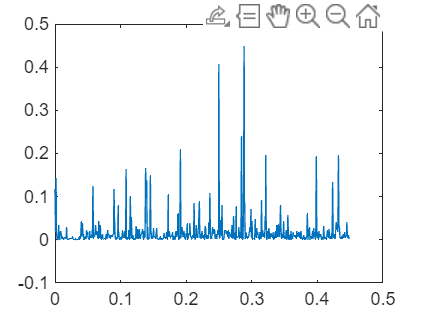


plot(linspace(0,max(u),size(u,1)),u(:,1))

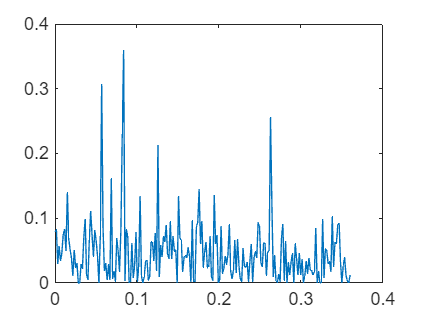

%set(gca,'xtick',linspace(min(xlim),max(xlim),size(u,1)),'xticklabel',uniqueWords)

plot(linspace(0,max(v),size(v,1)),v(:,1))

%set(gca,'xtick',linspace(min(xlim),max(xlim),size(v,1)),'xticklabel',sentences(1,:))

% Display the term-document matrix
disp('Term-Document Matrix:');

Term-Document Matrix:


disp(array2table(termDocumentMatrix, 'RowNames', uniqueWords, 'VariableNames', strcat("Sentence_", string(1:length(sentences)))));

Error using array2table (line 81)
The RowNames property must be a string array or a cell array, with each name containing one or more characters.


%--- Create a unique list of words (terms) ---%
allWords = unique([processedWords{:}]);

%%% Display allWords %%%
disp('Unique terms (allWords):');
disp(allWords); 
%---------------------------------------------%


% Initialize the matrix with zeros with size m x n (words x sentences)
termMatrix = zeros(length(allWords), length(sentences));

% Loop through each sentence and fill in the matrix
for n = 1:length(sentences)
    for m = 1:length(allWords)
        % Count the occurrence of each word in each sentence
        % strcmp checks if the word is in the string of words for the sentence
        % sum counts how many times the word appears (doesn't work atm)
        termMatrix(m, n) = sum(strcmp(processedWords{n}, allWords{m}));
    end
end


% Create a table with words as rows and sentences as columns
termMatrixTable = array2table(termMatrix, 'RowNames', allWords, 'VariableNames', arrayfun(@(x) ['Sentence ' num2str(x)], 1:size(termMatrix, 2), 'UniformOutput', false));

% Display the term-document matrix
disp('Term-Document Matrix (rows=words, columns=sentences):');
disp(termMatrixTable);